# **2024  OFDM Decoder for 6G**

% Code by: Sheng-Yuan Zheng
% % Refer to Yu-Chang Chen code, coperate with Zheng-Wei

## --- Preset ---

close all; clear; clc;
figOn2 = 1;
mode = 2;   % 1 : Experiment 2 : Simulation


## --- Parameter Setup ---

F_IF = 3.5;
F_down = F_IF*1e9*(1);
F_off = 0;
syncLv = [0.9 0.1];
channel = 4; % Channel on real time scope
load('Param_4QAM_IF 3.5GHz_BW 5GHz.mat');
load('Ref_4QAM_IF 3.5GHz_BW 5GHz.mat');

## --- File Reading ---


if mode == 1
    Rxwaveform = read_from_scope_Mac_1('169.254.166.172', channel); % change the ip of computer
    temp = Rxwaveform.YData';
    rx1 = (1)*temp;
    signaloutput = fopen(['RTS result_1','.txt'],'w');
    fprintf(signaloutput,'%f \n',temp);
    fclose(signaloutput);
%     rx1 =transpose(textread(RxSigName,'%f'));
%     disp(['processing: ',RxSigName]);    
elseif mode==2
    rx1 = rx1_simu;
    disp('--- In Simulation Mode ---');
end

--- In Simulation Mode ---


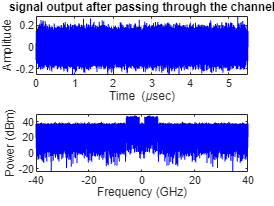


if figOn2 == 1
    figure('Name','received signal'),
    subplot(2,1,1),waveplot(rx1,'b',FsADC)
    title('signal output after passing through the channel'),grid on
    subplot(2,1,2),spectraplot(rx1,'b',FsADC)
end

## --- Noise Power Spectrum ---

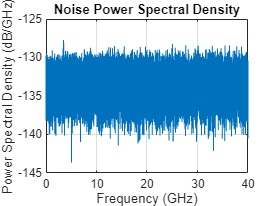

% 計算噪聲的功率譜密度
n = rx1 - tx10;
[pxx, f] = pwelch(n, [], [], [], FsADC);

% 繪圖
figure('Name', 'Noise Power Spectral Density');
plot(f / (10^9), 10*log10(pxx));
title('Noise Power Spectral Density');
xlabel('Frequency (GHz)');
ylabel('Power Spectral Density (dB/GHz)');
grid on;

N0 = mean(pxx);
disp(['Average Noise Power Spectral Density: ', num2str(mean(pxx)), ' W/Hz']);

Average Noise Power Spectral Density: 4.6821e-14 W/Hz


## --- Down Conversion ---

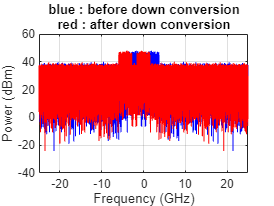


tstpRTS = 1 / FsADC;
timeWin = length(rx1) * tstpRTS;
tt = 0 : tstpRTS : timeWin - tstpRTS;
rx2i = rx1 .* cos(2 * pi * (F_off + F_down) * tt);
rx2q = rx1 .* sin(2 * pi * (F_off + F_down) * tt);
rx2 = rx2i - 1i * rx2q;

if figOn2 == 1
    figure('Name', 'Down-conv');
    spectraplot(rx1, 'b', FsDAC);
    grid on;
    hold on;
    title({'blue : before down conversion'; ...
        'red : after down conversion'});
    spectraplot(rx2, 'r', FsDAC);
    grid on;
    hold off;
end

## --- LPF ---

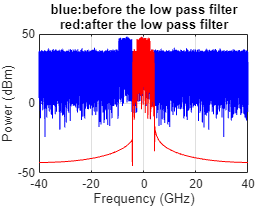

%%--- low pass filter (LPF) ---
load('LPF design for_4QAM_IF 3.5GHz_BW 5GHz.mat');  % design from encoder

rx3 = filter(LPFDesign, rx2); %low-pass the signal
if figOn2 == 1
    figure('Name','down-conv'),
    spectraplot(rx2,'b',FsADC),grid on;hold on;
    title({('blue:before the low pass filter'); ('red:after the low pass filter')})
    spectraplot(rx3,'r',FsADC),grid on;hold off;
end

## --- Synchronization ---

rx4 = resample(rx3, FsDAC, FsADC);

for corr = linspace(max(syncLv) , min(syncLv), 10)
    [syncIndex, syncValue] = winsync(rx4, tx7, RefLen, corr);
    disp(['... located', num2str(corr), 'at', num2str(syncIndex)]);
    if syncIndex < length(rx4) - length(tx7)    % Located
        rx5 = reshape(rx4(syncIndex : syncIndex + length(tx7) - 1), 1, []); 
        break
    elseif corr == min(syncLv)  % Intertupted
        disp('ERROR : Failed in synchronization!!');
        return
    end
end

... located0.9at132501
... located0.81111at3055


## --- Resample ---

rx6 = resample(rx5, FFTBW, FsDAC);

## --- CP Removal ---

rx7 = giRem(rx6, FFTsize, CPratio, SymLen);

## --- FFT ---

rx8 = fft(rx7);

## --- Zero-Padding Removal ---

rx9 = dezeropad(rx8, Nsc, FFTsize);

## --- Equalizer ---

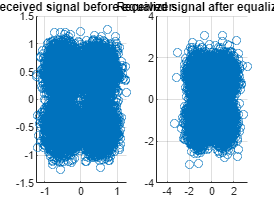

rx10 = ZFequalizer(rx9, tx3, Trainning_ratio);

if figOn2 == 1
    figure('Name', 'Equalization');
    subplot(1,2,1);
    scatter(real(rx9(:)), imag(rx9(:)));
    grid on;
    title('Received signal before equalizer');
    subplot(1,2,2);
    scatter(real(rx10(:)), imag(rx10(:)));
    grid on;
    title('Received signal after equalizer');

end

## --- De-Modulation ---

rx11 = demodulation(rx10, ModLv, Nsc, SymLen);

## --- P/S Conversion ---

rx12 = reshape(rx11, 1, []);
% rx12_training = reshape(rx11_training, 1, []);
rx12_payLoad = reshape(rx12, 1, []);

## --- Evaluation ---

% --- Error Count ---
BERCnt = biterr(tx1, rx12) / length(tx1);
BERMatrix = [];
BERMatrix = BERCnt;

% ---SNR Calculation (Time Domain) ---
SNRMatrix = [];
signalPower = mean(abs(tx10).^2) * (FsADC / FFTBW) * (FsADC / FsDAC) ;
noise = rx1 - tx10;
noisePower = mean(abs(noise).^2);
SNR2 = 10 * log10(signalPower / noisePower) - 2;
SNRMatrix = SNR2;

% --- CC HP Calculation ---
CCMatrix = [];
CC = Channel_Capacity(SigBW, signalPower, noisePower, 1);
CCMatrix = CC;

% --- Throughput HP Caulation ---

DR = DataRate(delta_f, CPratio, Trainning_ratio, ModLv, Nsc);
disp(['Data Rate:', num2str(DR/10^9), ' Gbps']);

Data Rate:1.2346 Gbps



% --- SE Caulation ---
SEMatrix = [];
SE = Spectral_Efficiency(DR, SigBW, signalPower, noisePower, 1);
SEMatrix = SE;

% --- EVM Statistics ---
derror = abs(tx3 - rx10) .^ 2;
dideal = abs(tx3) .^ 2;
EVM = sqrt(sum(derror) / sum(dideal));
BERSta = biterrorratio(ModLv, EVM);

% --- Output ---
disp(['Average Signal Power = ', num2str(signalPower *1000), ' mW']);

Average Signal Power = 29.9521 mW


disp(['Signal Power (dBm) = ', num2str(10*log10(signalPower *1000)-2), ' dBm']);

Signal Power (dBm) = 12.7643 dBm


disp(['Average Noise Power = ', num2str(noisePower *1000), ' mW']);

Average Noise Power = 1.8707 mW


disp(['Noise Power (dBm) = ', num2str(10*log10(noisePower *1000)), ' dBm']);

Noise Power (dBm) = 2.7201 dBm


disp(['SNR (Time Domain) = ', num2str(SNR2), 'dB']);

SNR (Time Domain) = 10.0442dB


disp(['BER (count) = ', num2str(BERCnt)]);

BER (count) = 0.0069167


disp(['CC (Shannon) = ', num2str(CC/10^9), ' Gbps']);

CC (Shannon) = 20.4419 Gbps


disp(['SE (Shannon) = ', num2str(SE), ' bps']);

SE (Shannon) = 2.3084 bps


disp(['BER(EVM) = ', num2str(BERSta)]);

BER(EVM) = 0.0087502


disp(['EVM = ', num2str(EVM)]);

EVM = 0.42087
